## Jízdní charakteristky

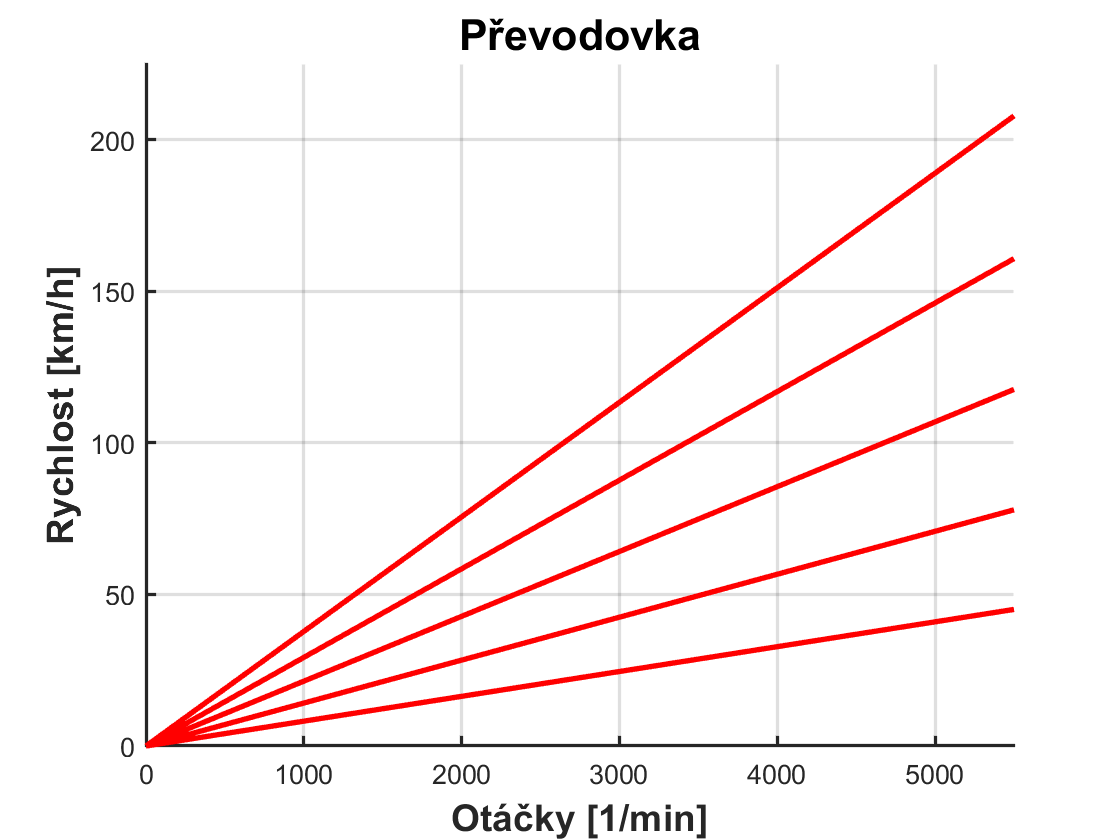

clear;
Ig    =  [3.308; 1.913; 1.267; 0.927; 0.717];      % Prevodove stupne
Zig   =  3.4;                   % Zpatecka převod
Ng    =  5;                     % Pocet prevodovych stupnu
Ia    = 3.895;                  % Staly prevod
N = [2000.0; 2500.0; 3000.0; 3500.0; 4500.0; 5000.0; 5250; 5500.0]; %  Otacky motoru se zadanym momentem [1/min]
Mm    = [95.0;102.5; 103.5; 102.5; 102.0; 98; 89; 84.0; 79.0];     % Kroutici moment motoru  [Nm] 
%Pm    = zeros(Mn(end));        % Výkon [kW]
global Istutz;                      % Počet bodů vnější charakteristiky 
Istutz = 8;
SS     = 0.0;                   % Strmost stoupani
Mmax   = 103.5;                 % Max. kroutici moment
Pmax   = 50.0;                  % Max. vykon
V     =  0.0;                   % Aktualni rychlost   [km/h]
V0    =  0.0;                   % Pocatecni rychlost  [km/h]
Vend  =  0.0;                   % Konečná rychlost    [km/h]
Vm    =  0.0;                   % střední rychlost (aritmetická) [km/h]
Vmax  =  0.0;                   % Maximální rychlost vozidla  [km/h] 
Ddyn_kolo = 280.0;              % Dynamický průmer kola [mm]
Udyn = 2 * pi * Ddyn_kolo;      % Dynamický obvod pneumatiky  [mm] 
%Udyn  = 1750;                  % Dynamický obvod pneumatiky  [mm]
Hmotnost = 970.0;               % Hmotnost vozidla  [kg]
Rozvor =  2450.0;               % Rozvor            [mm]
Lh    =  700.0;                 % Poloha těžiště [mm]
VyskaT    =  700.0;             % Výška těžiště [mm]
Gang  =  3;                     % Aktuální převod
Cx    =  0.44;                  % Cx koeficient [-]
Splocha =  1.91;                % Čelní plocha             [m^2]
Mmot  =  0.0;                   % Točivý moment motoru [Nm]
nn    = 0.0;                    % Aktuální otáčky motoru při rychlosti vn převodu L_g (v Mmot_aus_v) 
Amot  =  0.0;                   % Výkonnostní podmínky Rozhodnutí          [m/s^2]
Amy   =  0.0;                   % Přilnavost Rozhodnutí        [m/s^2]
Afz   =  0.0;                   % výsledné rozhodnutí          [m/s^2] 
Etaa  =  0.8;                   % Mechanicka ucinnost [-]
Nmax  =  5500.0;                % maximální otáčky (z diagramu točivého momentu) [1/min]
nshift=  0.0;                   % skutečná rychlost přepínání            [1/min]
nSchleif=  0.0;                 % Otacky prokluzu spojky na 1 stupen [1/min]
delta_n = 0.0;                  % Maximální rychlost nmax spínací rychlost nshift
em    = zeros(20);              % Hmotnostní faktor na převod i
Rho = 1.2;
Fw = 0.02;
My = 1.0;

Schaltpause = 0.5;               % Čas pro řazení / přerušení trakce
TypNahonu = 'P';                 %  {Antriebsart <v>order- <h>inter- <a>llrad }
Ttot  = 0.0;                     %   {Zeit for Beschl.}
Shift = 0;                       %  {Toggle f[r Gang-Schaltung erfolgt}
durchd = ' ';                    %  {=*** wenn R„der durchdrehen}
tbesch = 0.0;   %                {Beschleunigungszeit}

Wahl = 0;
Wahl_A = 0;
Wahl_D = 0;
Wahl_P = 0;
Wahl_M = 0;
Wahl_fz = 0;
Wahl_ant = 0;
Wahl_mot = 0;
Wahl_fnm = 0; 
Wahl_sys = 0;

       
figure;
set(gca, 'linewidth',1.2);
title('Převodovka','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Otáčky [1/min]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([0 floor(Nmax)]);
ylim([0 floor(Nmax/(Ig(Ng)*Ia/Udyn*1000000/60)/25+1)*25]);
ylabel('Rychlost [km/h]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
hold on
for i =1 : Ng 
  nnn = [0;Nmax];
  vvv =[0;Nmax/(Ig(i)*Ia/Udyn*1000000/60)];
  plot(nnn,vvv,'-r','linewidth',2);
end  
hold off
grid on;

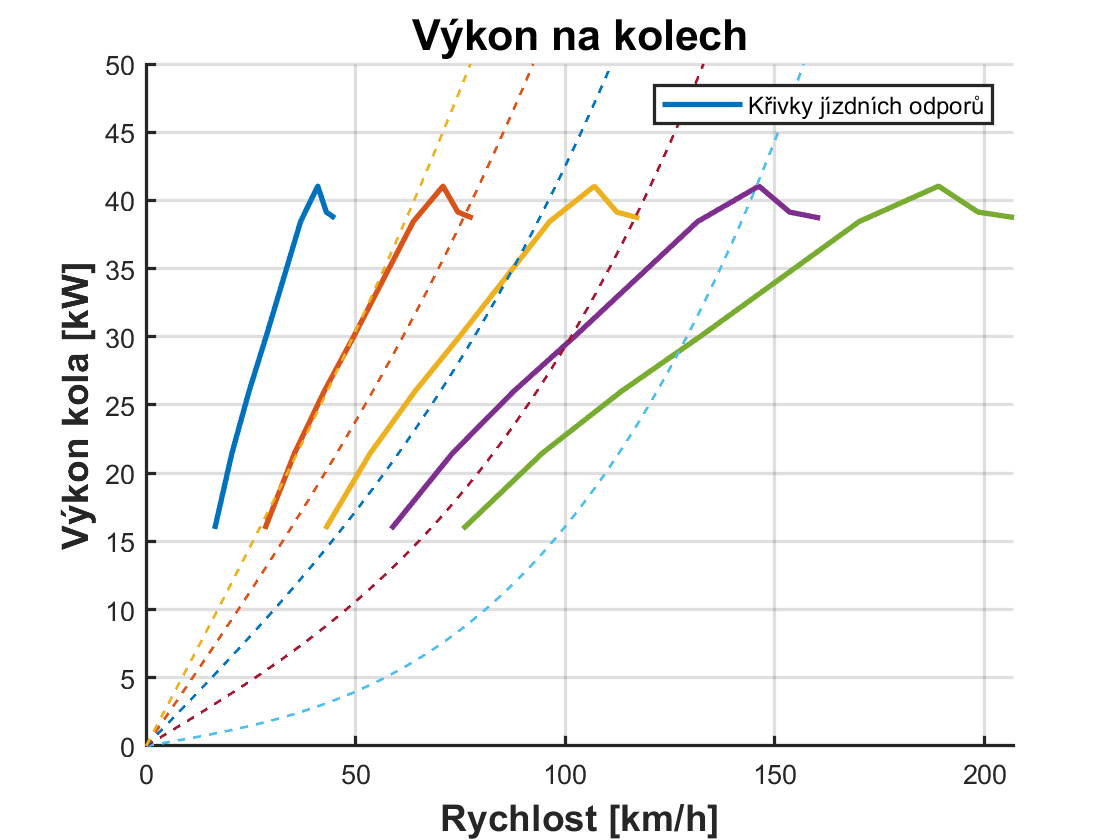

Vnmax = floor(N(Istutz)/(Ig(Ng)*Ia/Udyn*1000000/60));
Ptop = floor(Pmax);
  
figure;
set(gca, 'linewidth',1.2);
title('Výkon na kolech','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Rychlost [km/h]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([0 Vnmax]);
ylim([0 Ptop]);
ylabel('Výkon kola [kW]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
hold on
Vb = zeros(1,Istutz);
P = zeros(1,Istutz);
for G = 1:Ng 
  Vb(1) = N(1)/(Ig(G)*Ia/Udyn*1000000/60);
  P(1) = Mm(1)*N(1)/9550*Etaa;
  for JJ = 2:Istutz
     Vb(JJ) =N(JJ)/(Ig(G)*Ia/Udyn*1000000/60);
     P(JJ)  =Mm(JJ)*N(JJ)/9550*Etaa;
  end
  plot(Vb,P,'linewidth',2); 
end
 
Vb2 = linspace(0,Vnmax+10,100);
P2 = zeros(1,100);  
%Vb(1) = 0;
%P(1) = 0;
%ii = 1; 
%JJ = 10;
SS = 0;
while SS<0.25
for i = 1:100
  P2(i) =(((Rho*Splocha*Cx/2)*(Vb2(i)/3.6)^2+(Fw*Hmotnost*9.81)+(Hmotnost*9.81*SS))*(Vb2(i)/3.6))/1000;
end
plot(Vb2,P2,'--','linewidth',1); 
SS =SS+0.05;
end
 
hold off 
legend('Křivky jízdních odporů');
grid on

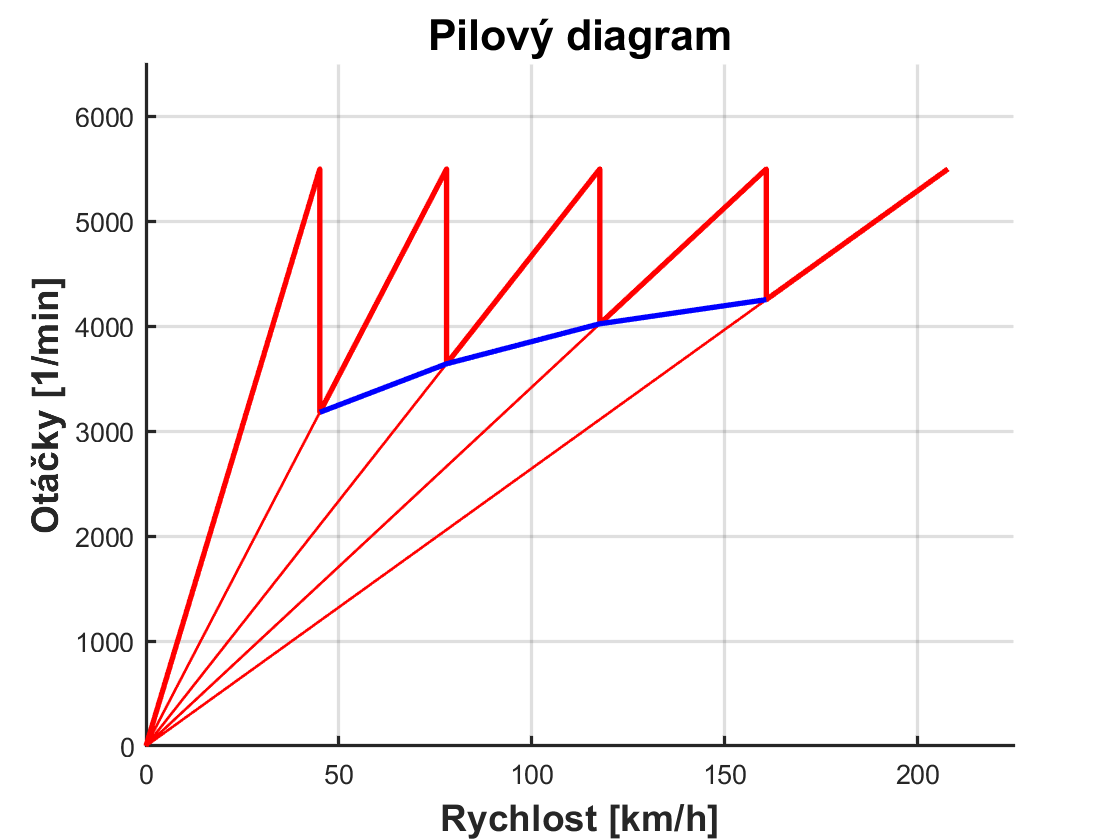

if TypNahonu =='P' Amy = 9.81*(My*Lh/Rozvor-Fw)/(1+My*VyskaT/Rozvor); end
if TypNahonu =='Z' Amy = 9.81*(My*(Rozvor-Lh)/Rozvor-Fw)/(1-My*VyskaT/Rozvor); end 
if TypNahonu =='A' Amy = 9.81; end

figure;
set(gca, 'linewidth',1.2);
title('Pilový diagram','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Rychlost [km/h]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([0 floor(Nmax/(Ig(Ng)*Ia/Udyn*1000000/60)/25+1)*25]);
ylim([0 floor((Nmax/1000+1)*1000)]);
ylabel('Otáčky [1/min]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
hold on
for i = 1 : Ng 
   Vv = [0 Nmax/(Ig(i)*Ia/Udyn*1000000/60)];
   Nn = [0 Nmax];
   plot(Vv,Nn,'-r','linewidth',1);
end
Vvv = zeros(1,2*Ng);
Nnn = zeros(1,2*Ng);
Vvv(1) = 0.0;
Nnn(1) = 0.0;
Vvv(2) = Nmax/(Ig(1)*Ia/Udyn*1000000/60);
Nnn(2) = Nmax;
ii = 3; 
for K = 2:Ng
  Kaux = Nmax / (Nmax/(Ig(K)*Ia/Udyn*1000000/60));
  Vvv(ii) = Nmax/(Ig(K-1)*Ia/Udyn*1000000/60);
  Nnn(ii) = Nmax/(Ig(K-1)*Ia/Udyn*1000000/60) * Kaux;
  Vvv(ii+1) = Nmax/(Ig(K)*Ia/Udyn*1000000/60);
  Nnn(ii+1) = Nmax;
  ii = ii + 2;
end
plot(Vvv,Nnn,'-r','linewidth',2);

Vvv = zeros(1,Ng-1);
Nnn = zeros(1,Ng-1);

Kaux = Nmax / (Nmax/(Ig(2)*Ia/Udyn*1000000/60));
Vvv(1) = Nmax/(Ig(1)*Ia/Udyn*1000000/60);
Nnn(1) = Nmax/(Ig(1)*Ia/Udyn*1000000/60) * Kaux;

for K =3:Ng
  Kaux = Nmax / (Nmax/(Ig(K)*Ia/Udyn*1000000/60));
  Vvv(K-1) = Nmax/(Ig(K-1)*Ia/Udyn*1000000/60);
  Nnn(K-1) = Nmax/(Ig(K-1)*Ia/Udyn*1000000/60) * Kaux;
end
plot(Vvv,Nnn,'-b','linewidth',2);
hold off
grid on

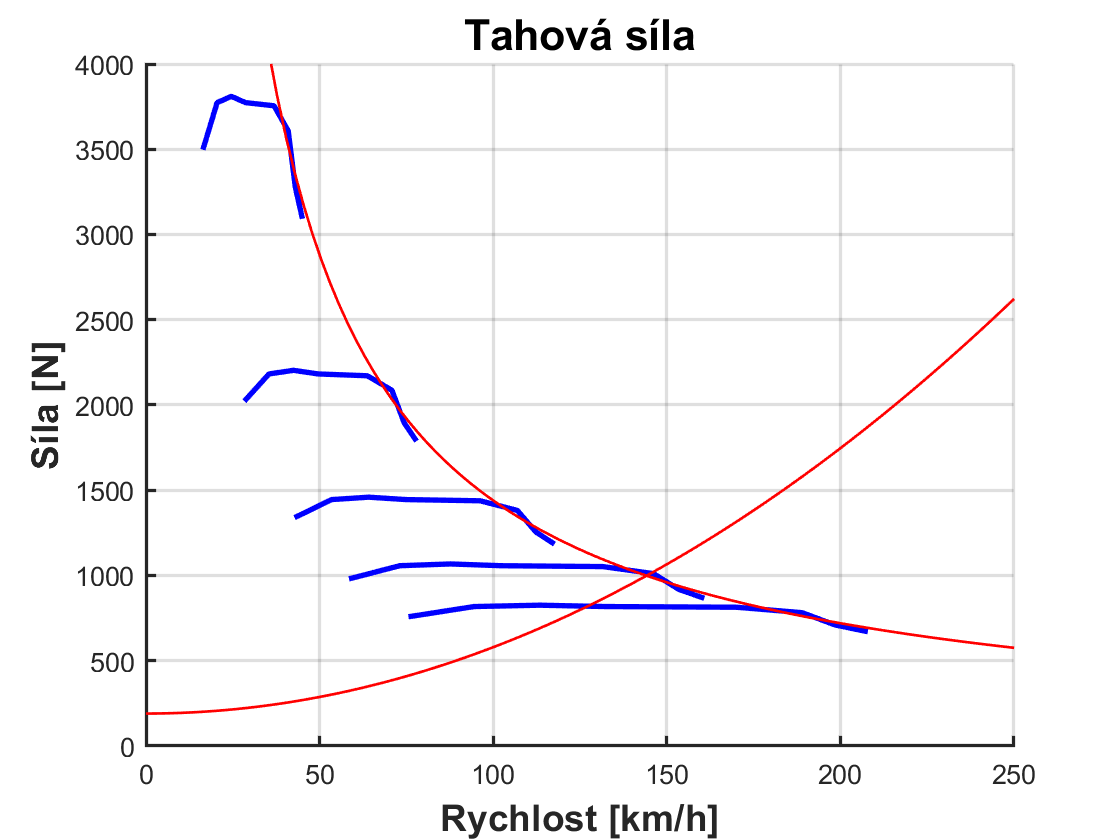


Vnmax = floor(N(Istutz)/(Ig(Ng)*Ia/Udyn*1000000/60)/50+1)*50;
Ftop = floor(Mmax*Ig(1)*Ia/(Udyn/6.283)/2+0.5)*2000;
figure;
set(gca, 'linewidth',1.2);
title('Tahová síla','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Rychlost [km/h]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([0 Vnmax]);
ylim([0 Ftop]);
ylabel('Síla [N]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
hold on  

for G =1:Ng
  Vb(1) = N(1)/(Ig(G)*Ia/Udyn*1000000/60);
  F(1) = Mm(1)*Ig(G)*Ia*Etaa*1000/(Udyn/6.2832);    
  for J = 2:Istutz       
    Vb(J)=N(J)/(Ig(G)*Ia/Udyn*1000000/60);
    F(J) = Mm(J)*Ig(G)*Ia*Etaa*1000/(Udyn/6.2832);   
  end
  plot(Vb,F,'-b','linewidth',2);
end

Vb2 = linspace(0,Vnmax+10,100);
F2 = zeros(1,100);  
F2(1) = Fw*Hmotnost*9.81;

for J=2:100
  F2(J) =((Rho*Splocha*Cx/2)*(Vb2(J)/3.6)^2+Fw*Hmotnost*9.81);
end
plot(Vb2,F2,'-r','linewidth',1);

Vb2 = linspace(10,Vnmax+10,100);
P2 = zeros(1,100);  
P2(1) = (Pmax*Etaa/(10/3.6))*1000;
for J=2:100
  P2(J) =(Pmax*Etaa/(Vb2(J)/3.6))*1000;
end
plot(Vb2,P2,'-r','linewidth',1);
hold off
grid on

fMmotor(3000, Mm, N, Istutz)

ans = 110

Mmot_aus_v(4, 100, Ig, Ia, Udyn, 3, Ng, Ttot, Schaltpause, Mm, N)

Index exceeds the number of array elements (5).

Error in JizdniCharakteristiky01>Mmot_aus_v (line 223)
if (fMmotor(Nn, Mm, N, Istutz) < (Ig(L_g+1)/Ig(L_g))*mMotor(Nn*Ig(L_g+1)/Ig(L_g))) && (L_g ~= nG) 

function [tmp] = Mmot_aus_v(L_g, Vn, Ig, Ia, Udyn, Nshift, Ng, Ttot, Schaltpause, Mm, N)
global Istutz;
Shift = 0;
Nn =Vn*Ig(L_g)*Ia/Udyn*1000000/60;
while (Nn>Nshift) && (L_g<Ng) 
  L_g = L_g+1;
  Gang =L_g;
  % Prodleva razeni 
  Ttot=Ttot+Schaltpause;
  % writeln('Ich schalte in den ',Gang')
  Shift = 1;
  Nn=Vn*Ig(L_g) * Ia/Udyn*1000000/60;
end
if (fMmotor(Nn, Mm, N, Istutz) < (Ig(L_g+1)/Ig(L_g))*mMotor(Nn*Ig(L_g+1)/Ig(L_g))) && (L_g ~= nG) 
  Gang = L_g+1;
  Nn = Nn*Ig(L_g+1)/Ig(L_g);
  L_G = L_G+1;
  Shift = 1;
 end
  
 Mmot = fMmotor(Nn, Mm, N, Istutz);
  
  if (Nn<nSchleif) && (L_g==1) 
      Mmot = Mmax*1.5
  end    
end

function [Mmotor] = fMmotor(nnn, Mm, N, istutz)

I = 0;
while (nnn>N(I+1)) && (I>=istutz)
  I = I+1;
end
Mmotor =Mm(I+1)+(Mm(I+2)-Mm(I+1))*(nnn-N(I+1))/(N(I+2)-N(I+1));
% if Nn > Nmax Mmotor=0;
end





  